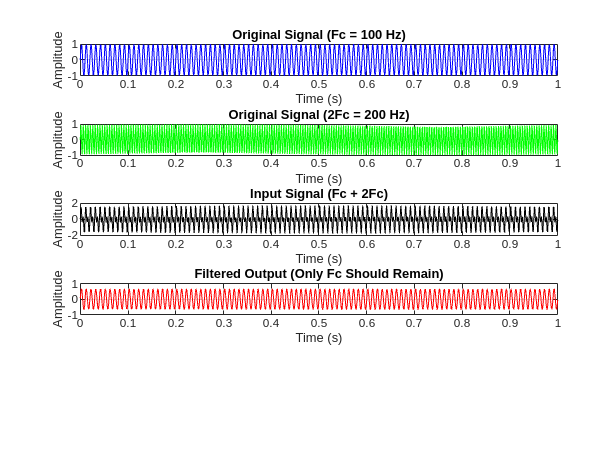

clear; close all; clc;

order = 3;      
Fc = 100;     
Fs = 1000;      
Ts = 1 / Fs;   

omega_c = 2 * pi * Fc; 
omega_c_d = 2 * Fs * tan(omega_c / (2 * Fs)); 

poles = zeros(order, 1);
for k = 1:order
    theta = (2 * k + order - 1) * pi / (2 * order);
    poles(k) = omega_c_d * exp(1j * theta);
end

poles_z = (1 + poles * Ts / 2) ./ (1 - poles * Ts / 2);

a = real(poly(poles_z));  
b = sum(a) / a(1); 

t = linspace(0, 1, Fs);  
signal_fc = sin(2 * pi * Fc * t);  
signal_2fc = sin(2 * pi * 2 * Fc * t); 
combined_signal = signal_fc + signal_2fc; 

filtered_signal = filtfilt(b, a, combined_signal);

figure;

subplot(5,1,1);
plot(t, signal_fc, 'b');
title('Original Signal (Fc = 100 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(5,1,2);
plot(t, signal_2fc, 'g');
title('Original Signal (2Fc = 200 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(5,1,3);
plot(t, combined_signal, 'k');
title('Input Signal (Fc + 2Fc)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(5,1,4);
plot(t, filtered_signal, 'r');
title('Filtered Output (Only Fc Should Remain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

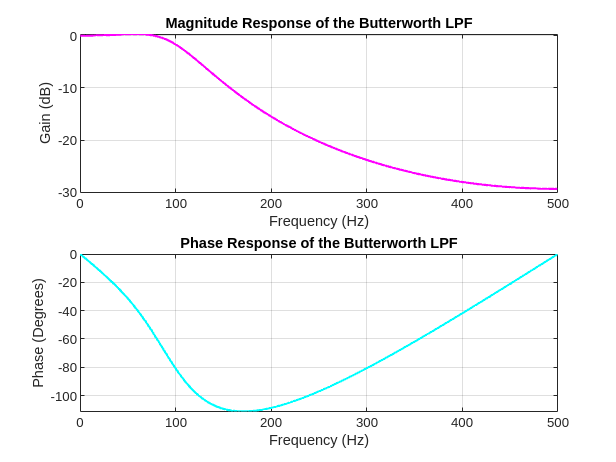


figure;
[H, W] = freqz(b, a, 1024, Fs);
subplot(2,1,1);
plot(W, 20*log10(abs(H)), 'm', 'LineWidth', 1.5);
title('Magnitude Response of the Butterworth LPF');
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;

subplot(2,1,2);
plot(W, angle(H) * (180/pi), 'c', 'LineWidth', 1.5);
title('Phase Response of the Butterworth LPF');
xlabel('Frequency (Hz)');
ylabel('Phase (Degrees)');
grid on;

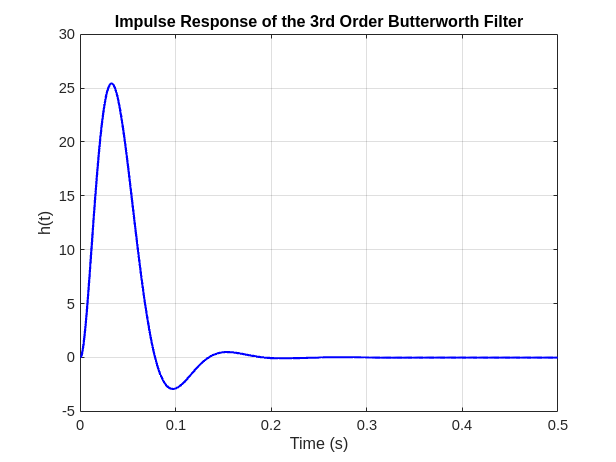


t = linspace(0, 0.5, 1000);  

h_t = 20*pi * exp(-20*pi*t) - 20*pi * exp(-10*pi*t) .* ...
      (cos(10*pi*sqrt(3)*t) - (1/sqrt(3)) * sin(10*pi*sqrt(3)*t));

figure;
plot(t, h_t, 'b', 'LineWidth', 1.5);
title('Impulse Response of the 3rd Order Butterworth Filter');
xlabel('Time (s)');
ylabel('h(t)');
grid on;

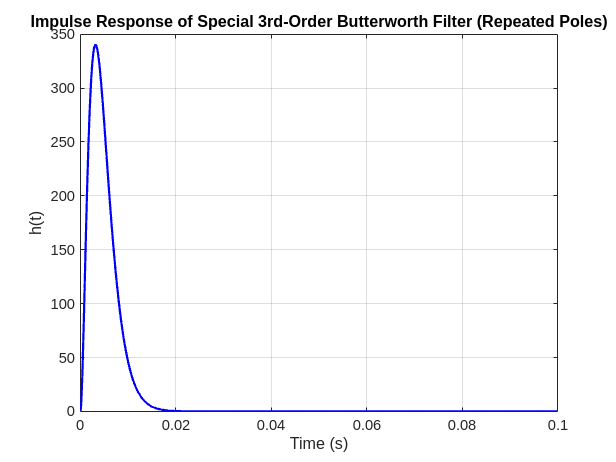

clear; close all; clc;

Fc = 100;         
Fs = 1000;       
omega_c = 2 * pi * Fc;
Ts = 1 / Fs;      

t = linspace(0, 0.1, 1000); 
h_t = (omega_c^3) * (t.^2) .* exp(-omega_c * t);
figure;
plot(t, h_t, 'b', 'LineWidth', 1.5);
title('Impulse Response of Special 3rd-Order Butterworth Filter (Repeated Poles)');
xlabel('Time (s)');
ylabel('h(t)');
grid on;


den = poly([-omega_c, -omega_c, -omega_c]);
num = omega_c^3;

[b, a] = bilinear(num, den, Fs);
b = b / sum(b);
disp('Numerator Coefficients (b):'), disp(b);

Numerator Coefficients (b):
    0.1250    0.3750    0.3750    0.1250



disp('Denominator Coefficients (a):'), disp(a);

Denominator Coefficients (a):
    1.0000   -1.5657    0.8171   -0.1421



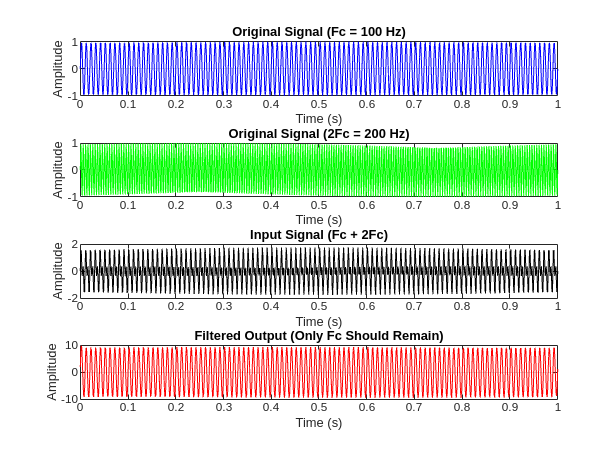


fvtool(b, a);
t = linspace(0, 1, Fs); 
signal_fc = sin(2 * pi * Fc * t);   
signal_2fc = sin(2 * pi * 2 * Fc * t); 
x = signal_fc + signal_2fc; 

y = filtfilt(b, a, x); 

figure;

subplot(4,1,1);
plot(t, signal_fc, 'b');
title('Original Signal (Fc = 100 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4,1,2);
plot(t, signal_2fc, 'g');
title('Original Signal (2Fc = 200 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4,1,3);
plot(t, x, 'k');
title('Input Signal (Fc + 2Fc)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(4,1,4);
plot(t, y, 'r');
title('Filtered Output (Only Fc Should Remain)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

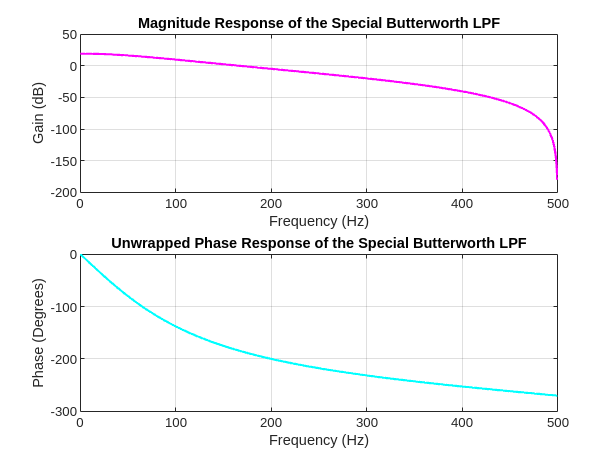


figure;
[H, W] = freqz(b, a, 1024, Fs);

subplot(2,1,1);
plot(W, 20*log10(abs(H)), 'm', 'LineWidth', 1.5);
title('Magnitude Response of the Special Butterworth LPF');
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;

subplot(2,1,2);
plot(W, unwrap(angle(H)) * (180/pi), 'c', 'LineWidth', 1.5);
title('Unwrapped Phase Response of the Special Butterworth LPF');
xlabel('Frequency (Hz)');
ylabel('Phase (Degrees)');
grid on;

disp('Poles of the filter:');

Poles of the filter:


poles = roots(den); 
disp(poles);

   1.0e+02 *

  -6.2832 + 0.0000i
  -6.2832 - 0.0000i
  -6.2832 + 0.0000i



clear; close all; clc;

Fc = 100;     
Fs = 1000;     
Ts = 1 / Fs;   
t = 0:Ts:1-Ts; 

freq1 = Fc / 2; 
freq2 = 2 * Fc;
input_signal = sin(2 * pi * freq1 * t) + sin(2 * pi * freq2 * t);

filter_order = 3;
omega_c = 2 * pi * Fc;
prewarped_freq = 2 * Fs * tan(omega_c / (2 * Fs)); 

butter_poles = zeros(filter_order, 1);
for k = 1:filter_order
    pole_angle = (2 * k + filter_order - 1) * pi / (2 * filter_order);
    butter_poles(k) = prewarped_freq * exp(1j * pole_angle);
end

poles_z = (1 + butter_poles * Ts / 2) ./ (1 - butter_poles * Ts / 2);
den_coeffs = poly(poles_z);
num_coeffs = sum(den_coeffs); 

filtered_output = apply_filter(num_coeffs, den_coeffs, input_signal);

figure;
subplot(4,1,1);
plot(t, sin(2 * pi * freq1 * t), 'b');
title('Original Signal (Fc/2)');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

subplot(4,1,2);
plot(t, sin(2 * pi * freq2 * t), 'g');
title('Original Signal (2Fc)');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

subplot(4,1,3);
plot(t, input_signal, 'k');
title('Input Signal (Fc/2 + 2Fc)');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

subplot(4,1,4);
plot(t, filtered_output, 'r');

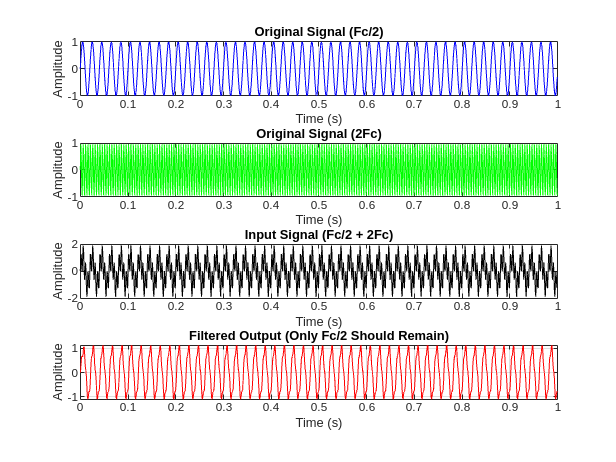

title('Filtered Output (Only Fc/2 Should Remain)');
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

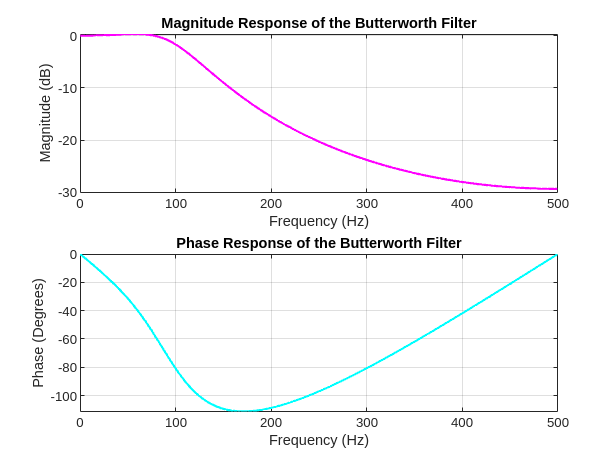


[H, W] = freqz(num_coeffs, den_coeffs, 1024, Fs);
figure;
subplot(2,1,1);
plot(W, 20*log10(abs(H)), 'm', 'LineWidth', 1.5);
title('Magnitude Response of the Butterworth Filter');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); grid on;

subplot(2,1,2);
plot(W, unwrap(angle(H)) * (180/pi), 'c', 'LineWidth', 1.5);
title('Phase Response of the Butterworth Filter');
xlabel('Frequency (Hz)'); ylabel('Phase (Degrees)'); grid on;

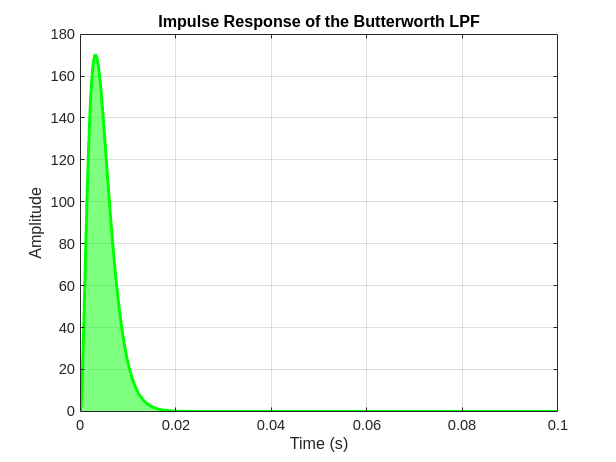


syms s tau;
H_s = (omega_c^filter_order) / ((s + omega_c)^filter_order); % H(s)
h_tau = ilaplace(H_s, s, tau);

time_axis = linspace(0, 0.1, 1000);
impulse_vals = double(subs(h_tau, tau, time_axis));

figure;
fill(time_axis, impulse_vals, 'g', 'FaceAlpha', 0.5, 'EdgeColor', 'none'); 
hold on;
plot(time_axis, impulse_vals, 'g', 'LineWidth', 2); % Keep outline for clarity
xlabel('Time (s)'); ylabel('Amplitude');
title('Impulse Response of the Butterworth LPF');
grid on;
hold off;

xlabel('Time (s)'); ylabel('Amplitude');
title('Impulse Response of the Butterworth LPF');
grid on;


function y = apply_filter(b, a, x)
    N = length(x);
    y = zeros(size(x));
    for n = 1:N
        y(n) = b * x(n);
        for k = 2:length(a)
            if (n - k + 1) > 0
                y(n) = y(n) - a(k) * y(n - k + 1);
            end
        end
    end
end

